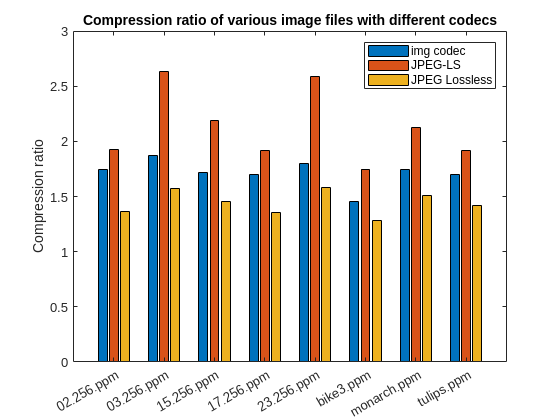

% jpeg_ls

i02 = [676063  ];
i03 = [630572    ];
i23 = [655362    ];
bike = [1482986    ];
monarch = [676642    ];
tulips = [693618    ];
i15 = [687555];
i17 = [694548];

lsmode = [676063 630572 655362 1482986 676642 693618 687555 694548];
jpeg = [612454 447299 456453 1231934 554947 616337 539429 615064];
jpeg2 = [866115 748308 747876 1679481 783125 830049 809417 872730];

imgsizes = [768*512*3 768*512*3 768*512*3 781*919*3 768*512*3 768*512*3 768*512*3 768*512*3];
imgsizes = [1179663 1179663 1179663 2153232 1179663 1179663 1179663 1179663];

%efs = (8 .* lsmode) ./ imgsizes;
%jpegfs = (8 .* jpeg) ./ imgsizes;
%jpegfs2 = (8 .* jpeg2) ./ imgsizes;

efs = 1 ./ ((lsmode) ./ imgsizes);
jpegfs =1 ./ ( (jpeg) ./ imgsizes);
jpegfs2 =1 ./ ( (jpeg2) ./ imgsizes);

bar(categorical({'02.256.ppm', '03.256.ppm', '23.256.ppm', 'bike3.ppm', 'monarch.ppm', 'tulips.ppm', '15.256.ppm', '17.256.ppm'}), [efs(1) jpegfs(1) jpegfs2(1); efs(2) jpegfs(2) jpegfs2(2); efs(3) jpegfs(3) jpegfs2(3); efs(4) jpegfs(4) jpegfs2(4); efs(5) jpegfs(5) jpegfs2(5); efs(6) jpegfs(6) jpegfs2(6); efs(7) jpegfs(7) jpegfs2(7); efs(8) jpegfs(8) jpegfs2(8);]);
title('Compression ratio of various image files with different codecs');
ylabel('Compression ratio');
legend('img codec', 'JPEG-LS', 'JPEG Lossless');